close all
clc
path = 'InvestmentReplica.mat';
load(path)

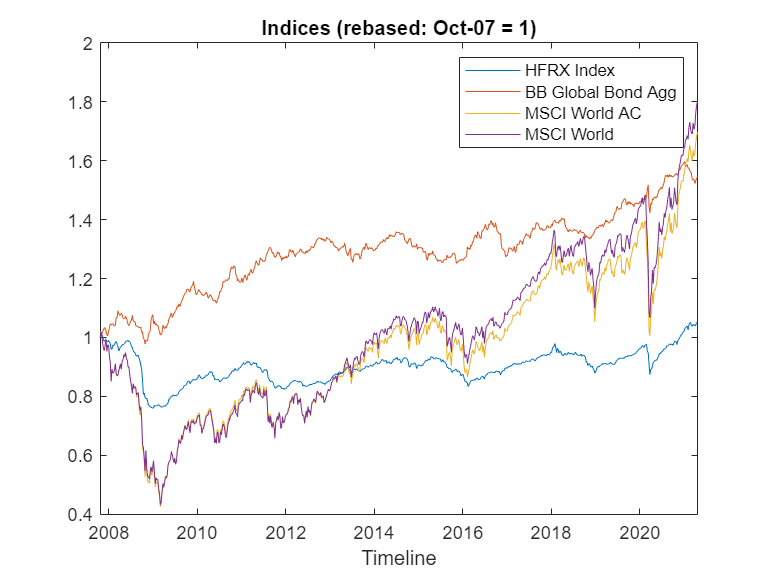

figure
plot(XTab.Date,XTab.HFRXGL/XTab.HFRXGL(1),'DisplayName','HFRX Index');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
plot(XTab.Date,XTab.MXWO/XTab.MXWO(1),'DisplayName','MSCI World');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

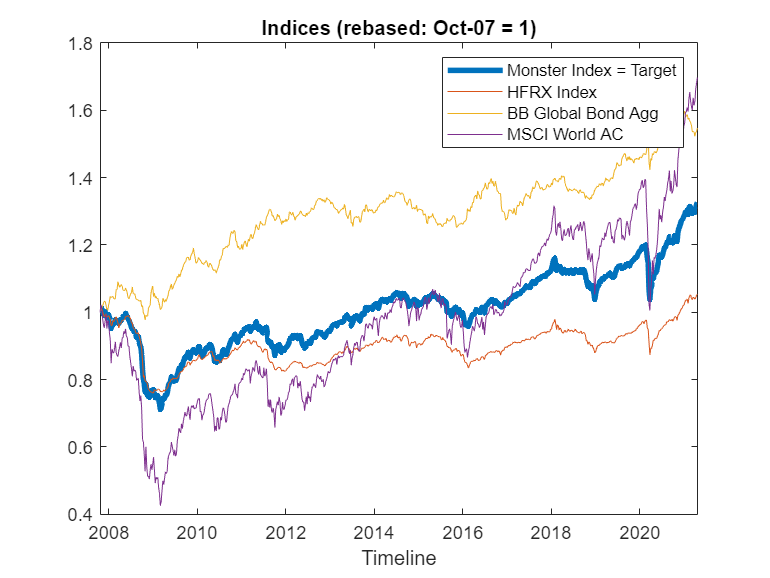

% Synthetic target weights
wHFRXGL = 0.5; 
wMXWO = 0.25;
wLEGATRUU = 0.25;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = (ret2price(y)); % "Monster Index" levels

figure
p = plot(XTab.Date,target,'DisplayName','Monster Index = Target');
p.LineWidth = 3;
hold on;
plot(XTab.Date,XTab.HFRXGL/XTab.HFRXGL(1),'DisplayName','HFRX Index');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

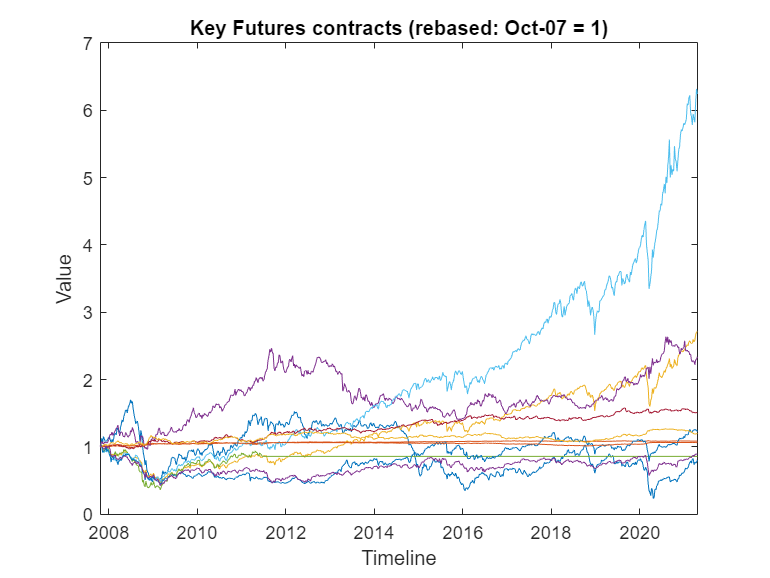

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

figure
plot(XTab.Date, ret2price(X))
xlabel('Timeline')
ylabel('Value')
title('Key Futures contracts (rebased: Oct-07 = 1)')

rollingWindow = 156; % in weeks (52 = 1Y, 104 = 2Y...)
i = 1;
b = zeros(size(X,2));
bENet2 = [];
rENet2 = [];
GrossExposure = [];
endSample = 0;
warning('off','all'); % avoid annoying warnings during the loop

while endSample <= (length(X) - 2)
    startSample = i;
    endSample = i+rollingWindow-1;
    [b,fitinfo] = lasso(X(startSample:endSample,:),y(startSample:endSample),'Alpha',0.85,'CV',5, 'Intercept',false);
%   lam = fitinfo.IndexMinMSE; % lambda corresponding to MinMSE (better fit)
%   lam = fitinfo.Index1SE; % lambda 1SE away from MinMSE (more robust)
    lam = round((fitinfo.Index1SE + fitinfo.IndexMinMSE)/2); % lambda half-way between MinMSE and 1SE away from MinMSE
    b = b(:,lam);
    GrossExposure = [GrossExposure; sum(abs(b))];
    bENet2 = [bENet2; b'];
    r = X(endSample + 1,:)*b;
    rENet2 = [rENet2; r];
    i = i+1;
end

warning('on','all'); % warnings on again